Part a) The below relations are derived by studing the geometry of the problem which is discussed in the report.

%constants, units are in meters
AO2 = 5

AO2 = 5

O1O2 = 12

O1O2 = 12

BO1 = 32

BO1 = 32

BC = 16

BC = 16

CO1_Y = 32

CO1_Y = 32

w2 = 1 %The angular velocity of theta 2, unit: rad/s

w2 = 1


syms t1(t2) t3(t2) t2(t) AO1(t)
%theta 2, the angular velocity is given to be 1 rad/s
t2(t) = w2 * t

$$t2(t) = t$$

AO1(t) = sqrt(AO2.^2 + O1O2.^2 - 2*AO2*O1O2*cos(t2+pi/2))

$$AO1(t) = \sqrt{169-120\,\cos\left(t+\frac{\pi }{2}\right)}$$

t1(t) = asin((O1O2 + AO2*sin(t2))/AO1)

$$t1(t) = \mathrm{asin}\left(\frac{5\,\sin\left(t\right)+12}{\sqrt{169-120\,\cos\left(t+\frac{\pi }{2}\right)}}\right)$$

t3(t) = simplify(asin((32 -BO1*t1)/BC))

$$t3(t) = -\mathrm{asin}\left(2\,\mathrm{asin}\left(\frac{5\,\sin\left(t\right)+12}{\sqrt{120\,\sin\left(t\right)+169}}\right)-2\right)$$

Plotting the t1, t2 and t3 with respect to time

%Since w2 is 1 rad/s, one revolution takes 2*pi seconds
time = linspace(0, 2*pi, 100);

th1 = t1(time);
th2 = t2(time);
th3 = t3(time);

% %plotting the values
% %the blue one is theta2, pink is theta 1 and yellow is theta 3
% plot(time, th2, 'b', time, th1, 'P', time, th3, 'y')
% title ("th1, th2 and th3 w respect to time");
% xlabel("time");
% ylabel("rad");

Part B) Ploting w1, w2 and w3 with respect to time

syms w1(t) w2(t) w3(t) 
w2(t) = t

$$w2(t) = t$$

w1(t) = diff(t1)

$$w1(t) = \begin{array}{l} \frac{\frac{5\,\cos\left(t\right)}{\sqrt{\sigma_{1}}}-\frac{60\,\sin\left(t+\frac{\pi }{2}\right)\,\left(5\,\sin\left(t\right)+12\right)}{{\sigma_{1}}^{3/2}}}{\sqrt{\frac{{\left(5\,\sin\left(t\right)+12\right)}^{2}}{120\,\cos\left(t+\frac{\pi }{2}\right)-169}+1}}\\ \mathrm{where}\\ \sigma_{1}=169-120\,\cos\left(t+\frac{\pi }{2}\right) \end{array}$$

w3(t) = diff(t3)

$$w3(t) = \begin{array}{l} -\frac{2\,\left(\frac{5\,\cos\left(t\right)}{\sqrt{\sigma_{1}}}-\frac{60\,\cos\left(t\right)\,\sigma_{2}}{{\sigma_{1}}^{3/2}}\right)}{\sqrt{1-\frac{{\sigma_{2}}^{2}}{\sigma_{1}}}\,\sqrt{1-{\left(2\,\mathrm{asin}\left(\frac{\sigma_{2}}{\sqrt{\sigma_{1}}}\right)-2\right)}^{2}}}\\ \mathrm{where}\\ \sigma_{1}=120\,\sin\left(t\right)+169\\ \sigma_{2}=5\,\sin\left(t\right)+12 \end{array}$$


omega2 = w2(time);
omega1 = w1(time);
omega3 = w3(time);

% %plotting the values
% %the blue one is w2, pink is w1 and yellow is w3
%  plot(time, omega2, 'b', time, omega1, 'P', time, omega3, 'y')
%  title ("w1, w2 and w3 w respect to time");
%  xlabel("time");
%  ylabel("omega");

Ploting the velocity of  the slider with respect to time

syms Vb(t) Vcb(t) Vc(t)
Vb(t) = BO1.*w1;
Vcb(t) = BC.*w3;
Vc(t) = Vb.*cos(pi/2 - t1) + Vcb.*cos(t3 - pi/2)

$$Vc(t) = \begin{array}{l} \frac{32\,\cos\left(\frac{\pi }{2}-\mathrm{asin}\left(\frac{\sigma_{3}}{\sqrt{169-\sigma_{1}}}\right)\right)\,\left(\frac{5\,\cos\left(t\right)}{\sqrt{169-\sigma_{1}}}-\frac{60\,\sin\left(t+\frac{\pi }{2}\right)\,\sigma_{3}}{{\left(169-\sigma_{1}\right)}^{3/2}}\right)}{\sqrt{\frac{{\sigma_{3}}^{2}}{\sigma_{1}-169}+1}}-\frac{32\,\cos\left(\frac{\pi }{2}+\mathrm{asin}\left(\sigma_{2}\right)\right)\,\left(\frac{5\,\cos\left(t\right)}{\sqrt{\sigma_{4}}}-\frac{60\,\cos\left(t\right)\,\sigma_{3}}{{\sigma_{4}}^{3/2}}\right)}{\sqrt{1-\frac{{\sigma_{3}}^{2}}{\sigma_{4}}}\,\sqrt{1-{\sigma_{2}}^{2}}}\\ \mathrm{where}\\ \sigma_{1}=120\,\cos\left(t+\frac{\pi }{2}\right)\\ \sigma_{2}=2\,\mathrm{asin}\left(\frac{\sigma_{3}}{\sqrt{\sigma_{4}}}\right)-2\\ \sigma_{3}=5\,\sin\left(t\right)+12\\ \sigma_{4}=120\,\sin\left(t\right)+169 \end{array}$$


vcx = Vc(time);
%ploting the values
plot(time, vcx, 'c')

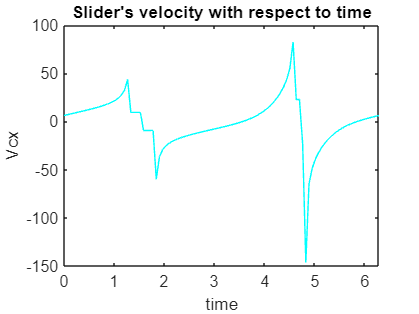

title ("Slider's velocity with respect to time");
xlabel("time");
ylabel("Vcx");

Part c) Determinig alpha 1, alpha2 and alpha2

clearly they can be achieved by differentiating the angular velocity with respect to time

syms a1(t) a2(t) a3(t) 
a2(t) = diff(w2)

$$a2(t) = 1$$

a1(t) = diff(w1)

$$a1(t) = \begin{array}{l} -\frac{\frac{5\,\sin\left(t\right)}{\sigma_{4}}+\frac{600\,\cos\left(t\right)\,\sigma_{1}}{\sigma_{3}}-\frac{10800\,{\sigma_{1}}^{2}\,\sigma_{5}}{{\left(169-120\,\sigma_{6}\right)}^{5/2}}+\frac{60\,\sigma_{6}\,\sigma_{5}}{\sigma_{3}}}{\sqrt{\sigma_{2}}}-\frac{\left(\frac{5\,\cos\left(t\right)}{\sigma_{4}}-\frac{60\,\sigma_{1}\,\sigma_{5}}{\sigma_{3}}\right)\,\left(\frac{120\,\sigma_{1}\,{\sigma_{5}}^{2}}{{\left(120\,\sigma_{6}-169\right)}^{2}}+\frac{10\,\cos\left(t\right)\,\sigma_{5}}{120\,\sigma_{6}-169}\right)}{2\,{\sigma_{2}}^{3/2}}\\ \mathrm{where}\\ \sigma_{1}=\sin\left(t+\frac{\pi }{2}\right)\\ \sigma_{2}=\frac{{\sigma_{5}}^{2}}{120\,\sigma_{6}-169}+1\\ \sigma_{3}={\left(169-120\,\sigma_{6}\right)}^{3/2}\\ \sigma_{4}=\sqrt{169-120\,\sigma_{6}}\\ \sigma_{5}=5\,\sin\left(t\right)+12\\ \sigma_{6}=\cos\left(t+\frac{\pi }{2}\right) \end{array}$$

a3(t) = diff(w3)

$$a3(t) = \begin{array}{l} \frac{2\,\left(\frac{5\,\sin\left(t\right)}{\sqrt{\sigma_{5}}}+\frac{600\,{\cos\left(t\right)}^{2}}{{\sigma_{5}}^{3/2}}-\frac{10800\,{\cos\left(t\right)}^{2}\,\sigma_{6}}{{\sigma_{5}}^{5/2}}-\frac{60\,\sin\left(t\right)\,\sigma_{6}}{{\sigma_{5}}^{3/2}}\right)}{\sqrt{\sigma_{2}}\,\sigma_{3}}+\frac{\sigma_{1}\,\left(\frac{120\,\cos\left(t\right)\,{\sigma_{6}}^{2}}{{\sigma_{5}}^{2}}-\frac{10\,\cos\left(t\right)\,\sigma_{6}}{\sigma_{5}}\right)}{{\sigma_{2}}^{3/2}\,\sigma_{3}}+\frac{4\,\sigma_{4}\,{\sigma_{1}}^{2}}{\left(\frac{{\sigma_{6}}^{2}}{\sigma_{5}}-1\right)\,{\left(1-{\sigma_{4}}^{2}\right)}^{3/2}}\\ \mathrm{where}\\ \sigma_{1}=\frac{5\,\cos\left(t\right)}{\sqrt{\sigma_{5}}}-\frac{60\,\cos\left(t\right)\,\sigma_{6}}{{\sigma_{5}}^{3/2}}\\ \sigma_{2}=1-\frac{{\sigma_{6}}^{2}}{\sigma_{5}}\\ \sigma_{3}=\sqrt{1-{\sigma_{4}}^{2}}\\ \sigma_{4}=2\,\mathrm{asin}\left(\frac{\sigma_{6}}{\sqrt{\sigma_{5}}}\right)-2\\ \sigma_{5}=120\,\sin\left(t\right)+169\\ \sigma_{6}=5\,\sin\left(t\right)+12 \end{array}$$


alpha2 = a2(time)

$$alpha2 = \left(\begin{array}{cccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccc} 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 \end{array}\right)$$

alpha1 = a1(time)

alpha3 = a3(time)


%plotting the values
%the blue one is a2, pink is a1 and yellow is a3
 plot(time, alpha2, 'b', time, alpha1, 'r', time, alpha3, 'y')

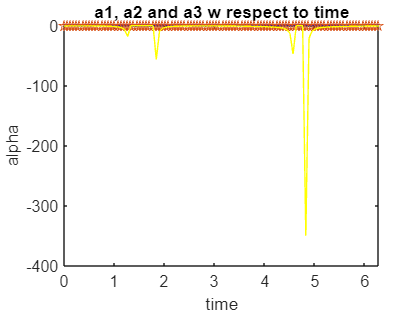

 title ("a1, a2 and a3 w respect to time");
 xlabel("time");
 ylabel("alpha");